**Symbolic Matlab Process for Lagrange Equation of Motion**

**2024-1**

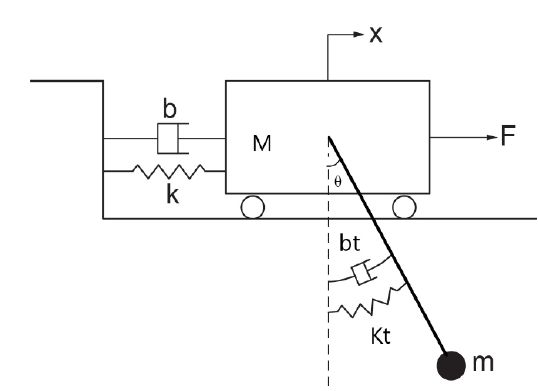

Las coordenadas de la masa $$m$$ se definen como $$(x+l \sin \theta,-l \cos \theta)$$, y sus componentes de velocidad son $$(\dot{x}+l \dot{\theta} \cos \theta, l \dot{\theta} \sin \theta)$$. Podemos escribir la energía cinética del sistema como


$$$$
T=\frac{m}{2}\left[(\dot{x}+l \dot{\theta} \cos \theta)^2+(l \dot{\theta} \sin \theta)^2 \right]+\frac{M}{2} \dot{x}^2=\frac{m}{2}\left(\dot{x}^2+l^2 \dot{\theta}^2 +2 l \dot{x} \dot{\theta} \cos \theta\right)+\frac{M}{2} \dot{x}^2
$$
$$


De manera similar, la energía potencial del sistema es $$V=\frac{1}{2} k x^2+\frac{1}{2} k_t \theta^2-m g l \cos \theta$$. La función de amortiguación del sistema (discipación) es $$D=\frac{1}{2} b \dot{x}^2+\frac{1}{2} b_t \dot{\theta}^2$$.

syms x1 x1d x1dd x2 x2d x2dd real;
syms u1 real;

Luego definimos nuestra variables, las coordenadas de posición y sus respectivas velocidades.

syms M m L g k k_t b b_t real;

% x1 = x
% x2 = theta

% Coordenadas masa m péndulo
p1x = x1;
p1y = 0;

p2x = x1 + L*sin(x2);
p2y = -L*cos(x2);

v1x = x1d;
v1y = 0;
v2x = v1x+L*cos(x2)*(x2d);
v2y = L*sin(x2)*(x2d);

Ahora calculemos las energías Cintéticas, Potencias y de Discipación

KE = 0.5*M*( v1x^2 + v1y^2) + 0.5*m*( v2x^2 + v2y^2);
KE = simplify(KE)

$$KE = \frac{M\,{\mathrm{x1d}}^{2}}{2}+\frac{m\,{\mathrm{x1d}}^{2}}{2}+\frac{L^{2}\,m\,{\mathrm{x2d}}^{2}}{2}+L\,m\,\mathrm{x1d}\,\mathrm{x2d}\,\cos\left(x_{2}\right)$$


PE = 0.5*k*x1^2 + 0.5*k_t*x2^2 -m*g*L*cos(x2);
PE = simplify(PE)

$$PE = \frac{k\,{x_{1}}^{2}}{2}+\frac{k_{t}\,{x_{2}}^{2}}{2}-L\,g\,m\,\cos\left(x_{2}\right)$$


Px1= u1;
Px2= 0;

% Disipación
DE = 0.5*b*x1d^2 + 0.5*b_t*x2d^2

$$DE = \frac{b\,{\mathrm{x1d}}^{2}}{2}+\frac{b_{t}\,{\mathrm{x2d}}^{2}}{2}$$

A partir de estas energías implementamos el formalismo Lagrangiano

Fifth, solve the Lagrangian equation

We have to get the Lagrangian eqn. $$\frac{d}{d t}\left(\frac{\partial T}{\partial \dot{q}_j}\right)-\frac{\partial T}{\partial q_j}+\frac{\partial V}{\partial q_j}=P_j$$

Let's obtain step by step.

$$\left(\frac{\partial T}{\partial \dot{q}}\right)}$$ is obtained by 

*pKEpx1d = diff(KE, x1d);*

To calculate, $$\frac{d}{d t}\left(\frac{\partial T}{\partial \dot{q}}\right)$$, we need the chain rule, that is


$$$$
\frac{d}{d t}\left(\frac{\partial T}{\partial \dot{q}_j}\right)=\sum_i^3\left\{\frac{\partial}{\partial q_i}\left(\frac{\partial T}{\partial \dot{q}_j}\right) \frac{d q_i}{d t}+\frac{\partial}{\partial \dot{q}_i}\left(\frac{\partial T}{\partial q_j}\right) \frac{d \dot{q}_i}{d t}\right\}
$$$$


*ddtpKEpx1d = diff(pKEpx1d,x1)x1d+ …*

*diff(pKEpx1d,x1d)*

*x1dd+ …*

*diff(pKEpx1d,x2)x2d + …*

*diff(pKEpx1d,x2d)*

*x2dd + …*

*diff(pKEpx1d,x3)x3d + …*

*diff(pKEpx1d,x3d)*

*x3dd;*

$$\frac{\partial T}{\partial q_j}, \frac{\partial V}{\partial q_j}$$ are easily obtained by

*pKEpx1 = diff(KE,x1);*

*pPEpx1 = diff(PE,x1);*

pKEpx1d = diff(KE,x1d);
ddtpKEpx1d = diff(pKEpx1d,x1)*x1d+ ...
             diff(pKEpx1d,x1d)*x1dd+ ...
             diff(pKEpx1d,x2)*x2d + ...
             diff(pKEpx1d,x2d)*x2dd;
pKEpx1 = diff(KE,x1);
pPEpx1 = diff(PE,x1);
pDEpx1 = diff(DE,x1d);


pKEpx2d = diff(KE,x2d);
ddtpKEpx2d = diff(pKEpx2d,x1)*x1d+ ...
             diff(pKEpx2d,x1d)*x1dd+ ...
             diff(pKEpx2d,x2)*x2d + ...
             diff(pKEpx2d,x2d)*x2dd;
pKEpx2 = diff(KE,x2);
pPEpx2 = diff(PE,x2);
pDEpx2 = diff(DE,x2d);

eqx1 = simplify( ddtpKEpx1d - pKEpx1 + pPEpx1 + pDEpx1 - Px1);
eqx2 = simplify( ddtpKEpx2d - pKEpx2 + pPEpx2 + pDEpx1 - Px2);

Ahora solucionamos para los términos $\ddot{x}\quad \text{y}\quad \ddot{\theta}$

Sol = solve([eqx1,eqx2],[x1dd,x2dd]);
Sol.x1dd = simplify(Sol.x1dd);
Sol.x2dd = simplify(Sol.x2dd);

syms y1 y2 y3 y4
fx1 = y2

$$fx1 = y_{2}$$

fx2=subs(Sol.x1dd,{x1,x1d,x2,x2d},{y1,y2,y3,y4})

$$fx2 = \frac{L\,u_{1}+b\,y_{2}\,\cos\left(y_{3}\right)+k_{t}\,y_{3}\,\cos\left(y_{3}\right)-L\,b\,y_{2}-L\,k\,y_{1}+L^{2}\,m\,{y_{4}}^{2}\,\sin\left(y_{3}\right)+L\,g\,m\,\cos\left(y_{3}\right)\,\sin\left(y_{3}\right)}{L\,\left(-m\,{\cos\left(y_{3}\right)}^{2}+M+m\right)}$$

fx3 = y4

$$fx3 = y_{4}$$

fx4=subs(Sol.x2dd,{x1,x1d,x2,x2d},{y1,y2,y3,y4})

$$fx4 = -\frac{M\,b\,y_{2}+M\,k_{t}\,y_{3}+b\,m\,y_{2}+k_{t}\,m\,y_{3}+L\,m\,u_{1}\,\cos\left(y_{3}\right)+L\,g\,m^{2}\,\sin\left(y_{3}\right)+\frac{L^{2}\,m^{2}\,{y_{4}}^{2}\,\sin\left(2\,y_{3}\right)}{2}+L\,M\,g\,m\,\sin\left(y_{3}\right)-L\,b\,m\,y_{2}\,\cos\left(y_{3}\right)-L\,k\,m\,y_{1}\,\cos\left(y_{3}\right)}{L^{2}\,m\,\left(-m\,{\cos\left(y_{3}\right)}^{2}+M+m\right)}$$


F = [fx1;fx2;fx3;fx4]

$$F = \begin{array}{l} \left(\begin{array}{c} y_{2}\\ \frac{L\,u_{1}+b\,y_{2}\,\cos\left(y_{3}\right)+k_{t}\,y_{3}\,\cos\left(y_{3}\right)-L\,b\,y_{2}-L\,k\,y_{1}+L^{2}\,m\,{y_{4}}^{2}\,\sin\left(y_{3}\right)+L\,g\,m\,\cos\left(y_{3}\right)\,\sin\left(y_{3}\right)}{L\,\sigma_{1}}\\ y_{4}\\ -\frac{M\,b\,y_{2}+M\,k_{t}\,y_{3}+b\,m\,y_{2}+k_{t}\,m\,y_{3}+L\,m\,u_{1}\,\cos\left(y_{3}\right)+L\,g\,m^{2}\,\sin\left(y_{3}\right)+\frac{L^{2}\,m^{2}\,{y_{4}}^{2}\,\sin\left(2\,y_{3}\right)}{2}+L\,M\,g\,m\,\sin\left(y_{3}\right)-L\,b\,m\,y_{2}\,\cos\left(y_{3}\right)-L\,k\,m\,y_{1}\,\cos\left(y_{3}\right)}{L^{2}\,m\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-m\,{\cos\left(y_{3}\right)}^{2}+M+m \end{array}$$

Now lets compute the Jacobian to linearize the system

% compute jacobian
A_symbolic = jacobian(F, [y1,y2,y3,y4])

$$A\_symbolic = \begin{array}{l} \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ -\frac{k}{\sigma_{2}} & -\frac{L\,b-b\,\cos\left(y_{3}\right)}{L\,\sigma_{2}} & \frac{k_{t}\,\cos\left(y_{3}\right)-b\,y_{2}\,\sin\left(y_{3}\right)-k_{t}\,y_{3}\,\sin\left(y_{3}\right)+L^{2}\,m\,{y_{4}}^{2}\,\cos\left(y_{3}\right)+L\,g\,m\,{\cos\left(y_{3}\right)}^{2}-L\,g\,m\,{\sin\left(y_{3}\right)}^{2}}{L\,\sigma_{2}}-\frac{2\,m\,\cos\left(y_{3}\right)\,\sin\left(y_{3}\right)\,\left(L\,u_{1}+b\,y_{2}\,\cos\left(y_{3}\right)+k_{t}\,y_{3}\,\cos\left(y_{3}\right)-L\,b\,y_{2}-L\,k\,y_{1}+L^{2}\,m\,{y_{4}}^{2}\,\sin\left(y_{3}\right)+L\,g\,m\,\cos\left(y_{3}\right)\,\sin\left(y_{3}\right)\right)}{L\,{\sigma_{2}}^{2}} & \frac{2\,L\,m\,y_{4}\,\sin\left(y_{3}\right)}{\sigma_{2}}\\ 0 & 0 & 0 & 1\\ \frac{k\,\cos\left(y_{3}\right)}{L\,\sigma_{2}} & -\frac{M\,b+b\,m-L\,b\,m\,\cos\left(y_{3}\right)}{\sigma_{1}} & \frac{2\,\cos\left(y_{3}\right)\,\sin\left(y_{3}\right)\,\left(M\,b\,y_{2}+M\,k_{t}\,y_{3}+b\,m\,y_{2}+k_{t}\,m\,y_{3}+L\,m\,u_{1}\,\cos\left(y_{3}\right)+L\,g\,m^{2}\,\sin\left(y_{3}\right)+\frac{L^{2}\,m^{2}\,{y_{4}}^{2}\,\sin\left(2\,y_{3}\right)}{2}+L\,M\,g\,m\,\sin\left(y_{3}\right)-L\,b\,m\,y_{2}\,\cos\left(y_{3}\right)-L\,k\,m\,y_{1}\,\cos\left(y_{3}\right)\right)}{L^{2}\,{\sigma_{2}}^{2}}-\frac{M\,k_{t}+k_{t}\,m-L\,m\,u_{1}\,\sin\left(y_{3}\right)+L\,g\,m^{2}\,\cos\left(y_{3}\right)+L^{2}\,m^{2}\,{y_{4}}^{2}\,\cos\left(2\,y_{3}\right)+L\,M\,g\,m\,\cos\left(y_{3}\right)+L\,b\,m\,y_{2}\,\sin\left(y_{3}\right)+L\,k\,m\,y_{1}\,\sin\left(y_{3}\right)}{\sigma_{1}} & -\frac{m\,y_{4}\,\sin\left(2\,y_{3}\right)}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L^{2}\,m\,\sigma_{2}\\ \sigma_{2}=-m\,{\cos\left(y_{3}\right)}^{2}+M+m \end{array}$$

B_symbolic = jacobian(F, u1);

Finally we evaluate the equillibrium points

% compute matrices A, B, C, D
A_algebraic = simplify(subs(A_symbolic, {M m L g k k_t b b_t y1 y2 y3 y4 u1}, ...
                [sym(1) sym(0.45) sym(0.6) sym(9.81) sym(0.01) sym(0.001) sym(0.001) sym(0.001) sym(0) sym(0) sym(0.0) sym(0.00) sym(0.00)]));
B_algebraic = simplify(subs(B_symbolic, {M m L g k k_t b b_t y1 y2 y3 y4 u1}, ...
                [sym(1) sym(0.45) sym(0.6) sym(9.81) sym(0.01) sym(0.001) sym(0.001) sym(0.001) sym(0) sym(0) sym(0.0) sym(0.00) sym(0.00)]));

Now we compute the numeric expressions

% compute numerical values            
A_eval = eval(A_algebraic);
B_eval = eval(B_algebraic);

Now we are able to create the state-space system. Let us assume that we can measere both $x$ and $\theta$

C = [1 0 0 0; 0 0 1 0];
D = [0;0]

sysLTI = ss(A_eval,B_eval,C,D)

sysLTI =
 
  A = 
              x1         x2         x3         x4
   x1          0          1          0          0
   x2      -0.01  0.0006667      4.416          0
   x3          0          0          0          1
   x4    0.01667  -0.007284     -23.72          0
 
  B = 
           u1
   x1       0
   x2       1
   x3       0
   x4  -1.667
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.


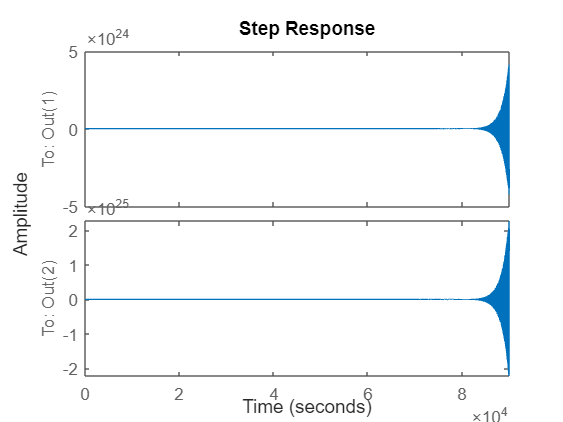

step(sysLTI)